# OpenAI Images

[https://beta.openai.com/docs/guides/images/introduction](https://beta.openai.com/docs/guides/images/introduction)

## Set-up Python

pyenv(Version="..\env\Scripts\python.exe",ExecutionMode="OutOfProcess")

## Set-up OpenAI

Save OpenAI key in secrets.toml file

pythonCode = ["import tomli;"; ...
    "f = open('secrets.toml','rb')"; ...
    "toml_dict = tomli.load(f)"; ...
    "key = toml_dict['OPEN_AI_KEY']"; ...
    "f.close()"];
OPEN_AI_KEY = pyrun(pythonCode,"key");
% OPEN_AI_KEY = string(OPEN_AI_KEY);

Or enter the API key directly in the notebook (don't share your key with others):

% OPEN_AI_KEY = "";

Set-up the API with the key:

pyrun("import openai;openai.api_key = OPEN_AI_KEY",OPEN_AI_KEY = OPEN_AI_KEY)

## Image Generation

[https://beta.openai.com/docs/guides/images/generations](https://beta.openai.com/docs/guides/images/generations)

p = "a funny corgi cartoon style";
n = 1;
s = "512x512";
pythonCode = "import openai; response = openai.Image.create(prompt=p,n=int(n),size=s);image_url = response['data'][0]['url']";
image_url = pyrun(pythonCode,"image_url",p=p,n=n,s=s);

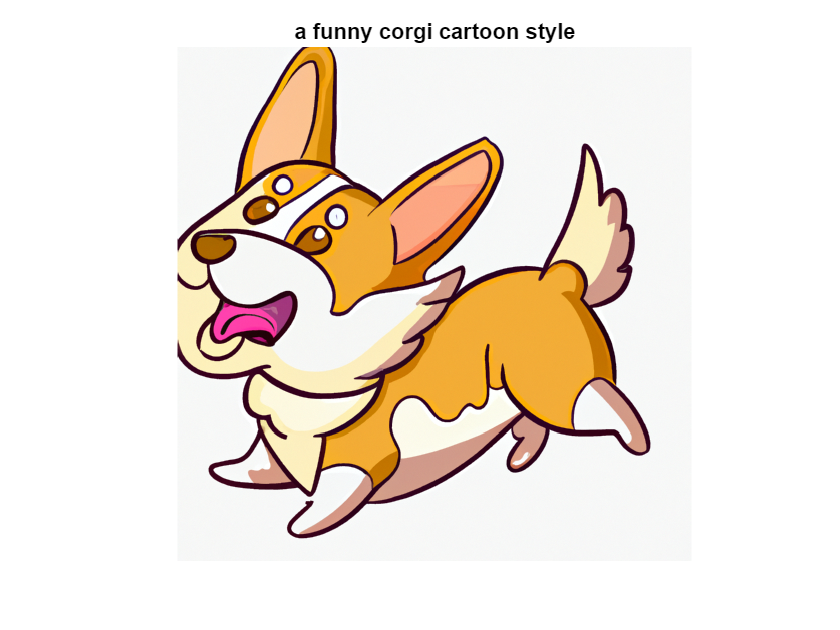

im = imread(string(image_url));
imshow(im)
title(p)